%% Define Constants
m = 285;
Iz = 100;
g = 9.81;
x1 = 0.7675;
x2 = -0.7675;
y1 = 0.6475;
y2 = 0.6285;
z = 0.1816;
N_bp = [200 400 600 900 1000 1200];
C_tb = [15000 20000 25000 30000 30000 30000];

% Get Dynamic Equation
[r_ss, sym] = get_r_ss(m, Iz, x1, x2);

% Setup Solver
u_vec = 1:30;
d_vec = (-pi/10):(pi/100):(pi/10);

nx = length(u_vec);
ny = length(d_vec);

[u_grid, d_grid] = meshgrid(u_vec, d_vec);
u_all = u_grid(:);
d_all = d_grid(:);
n = length(d_all);
r_all = zeros(n, 1);

% get yaw rate for all sample points
for i = 1:n
    ax0 = 0;
    ay0 = 0;
    u = u_all(i);
    d = d_all(i);

    N0 = double(compute_N(ax0, ay0, m, g, x1, x2, y1, y2, z));
    C0 = compute_C(N_bp, C_tb, N0);
    val = [C0; u; d];
    r0 = compute_r(r_ss, sym, val)

    for j = 1:1
        ax0 = 0;
        ay0 = r0*u;
        N0 = double(compute_N(ax0, ay0, m, g, x1, x2, y1, y2, z));
        C0 = compute_C(N_bp, C_tb, N0);
        val = [C0; u; d];
        
        r0 = compute_r(r_ss, sym, val);
    end

    r_all(i) = r0;
end


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1433


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1023


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0614


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0409


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0205


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0205


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0409


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0614


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1023


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1433


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0409


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0409


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0614


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0614


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.0819


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7163


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5117


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1023


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1023


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5117


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7163


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1228


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0029


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7163


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1433


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1433


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7163


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0029


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3098


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1637


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3098


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6578


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.1842


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6578


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0466


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2047


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0466


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2513


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0262


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8010


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5759


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3508


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1257


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9005


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6754


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4503


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2251


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2251


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4503


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6754


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9005


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1257


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3508


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5759


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8010


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0262


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2513


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4560


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2104


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.9648


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7192


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2456


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7192


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.9648


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2104


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4560


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.6606


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.3946


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.1285


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8624


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5964


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3303


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0643


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7982


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5321


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2661


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2661


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5321


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7982


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0643


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3303


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5964


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8624


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.1285


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.3946


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.6606


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2922


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0057


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7192


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.2865


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4326


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7192


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0057


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2922


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.7630


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.1490


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5350


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3070


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9210


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5350


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.1490


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.7630


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.2746


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.6197


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2922


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.9648


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3098


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3275


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6549


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3098


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.9648


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2922


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.6197


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.2746


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.4793


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.1314


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.7834


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4355


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0876


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7396


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3917


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0438


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6959


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3479


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3479


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6959


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0438


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3917


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7396


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0876


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4355


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.7834


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.1314


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.4793


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.3156


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2104


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3684


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7368


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4736


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8420


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2104


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.3156


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.8886


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.4998


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.1109


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.7220


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.3332


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.9443


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5554


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1666


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.7777


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.3889


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.3889


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.7777


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1666


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5554


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.9443


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.3332


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.7220


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.1109


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.4998


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.8886


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.0933


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.2746


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0466


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4093


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8187


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6373


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0466


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.2746


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.0933


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.2979


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.8681


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.0086


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.1490


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7192


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4298


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.8596


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2894


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7192


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.1490


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.5788


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.0086


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.8681


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.2979


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.5026


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.0523


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.6021


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.1518


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.7016


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2513


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8010


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.3508


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9005


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4503


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4503


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9005


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.3508


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8010


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2513


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.7016


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.1518


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.6021


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.0523


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.5026


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.7073


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.2365


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.7658


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.2951


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.8244


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.3536


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8829


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4122


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9415


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4707


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4707


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9415


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4122


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8829


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.3536


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.8244


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.2951


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.7658


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.2365


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.7073


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.9119


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.4207


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.9295


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.9648


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.4736


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.4912


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.9824


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.4736


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.9648


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.9472


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.9295


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.4207


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.9119


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.1166


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.6049


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.0933


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.5816


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.5583


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.0466


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5350


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5117


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5117


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0233


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5350


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.0466


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.5583


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.5816


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.0933


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.6049


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.1166


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.3213


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.7891


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.2570


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.7249


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.1928


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.6606


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.1285


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.5964


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.0643


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5321


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5321


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.0643


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.5964


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.1285


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.6606


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.1928


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.7249


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.2570


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.7891


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.3213


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.5259


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.9733


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.4207


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.8681


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.3156


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.7630


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2104


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.6578


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5526


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1052


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.6578


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2104


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.7630


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.3156


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.8681


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.4207


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.9733


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.5259


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.7306


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.1575


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.5845


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.0114


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.2922


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7192


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5731


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1461


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7192


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.2922


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.8653


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.4384


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.0114


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.5845


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.1575


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.7306


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.9353


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.3417


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.7482


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.1547


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.5612


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.9676


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.3741


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.7806


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.1871


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.5935


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.5935


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.1871


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.7806


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.3741


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.9676


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.5612


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.1547


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.7482


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.3417


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.9353


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -6.1399


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -5.5259


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.9119


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -4.2979


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.8420


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -1.2280


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = -0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 0.6140


Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.2280


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 1.8420


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 2.4560


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.0700


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 3.6840


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.2979


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 4.9119


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 5.5259


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


r0 = 6.1399


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


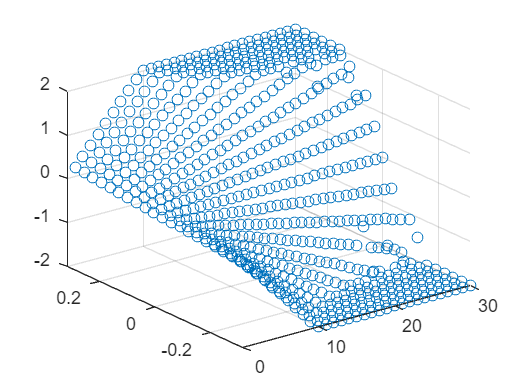


r_grid = reshape(r_all, [ny nx]);

%% Plotting
scatter3(u_all, d_all, max(min(r_all, 2),-2))

function [r_ss, S] = get_r_ss(m, Iz, x1, x2)
    %% Define State Symbolics
    r = sym("r",[1 1], "real");
    v = sym("v",[1 1], "real");
    C = sym("C",[4 1], "real");
    N = sym("N",[4 1], "real");
    
    %% Define Control Symbolics
    u = sym("u", [1 1], "real");
    d = sym("d", [1 1], "real");

    S = [C; u; d];

    % The Dynamics
    Cf = C(1) + C(2);
    Cr = C(3) + C(4);
    r_dot = 0 == (((-x1*Cf)-(x2*Cr))/(Iz*u))*v + (((-x1^2*Cf)-(x2^2*Cr))/(Iz*u))*r + ((x1*Cf)/Iz)*d;
    v_dot = 0 == (((-Cf)-(Cr))/(m*u))*v + (((-x1*Cf)-(x2*Cr))/(m*u))*r -(u*r) + ((Cf)/m)*d;
    v_ss = solve(v_dot,v);
    r_dot_ss = subs(r_dot,v,v_ss);
    r_ss = solve(r_dot_ss,r);
end

function N = compute_N(ax, ay, m, g, x1, x2, y1, y2, z)
    %% Find Minimum Energy Solution
    H = eye(4);
    f = [];
    A = [];
    b = [];
    Aeq = [1 1 1 1; y1 -y1 y2 -y2; x1 x1 x2 x2];
    beq = [m*g; -m*z*ay; -m*z*ax];
    lb = [0; 0; 0; 0];
    ub = [];
    
    N = quadprog(H,f,A,b,Aeq,beq,lb,ub);
end

function C = compute_C(N_bp, C_tb, N)
    C = pchip(N_bp, C_tb, N);
end

function r = compute_r(r_ss, sym, val)
    r = double(subs(r_ss, sym, val));
end